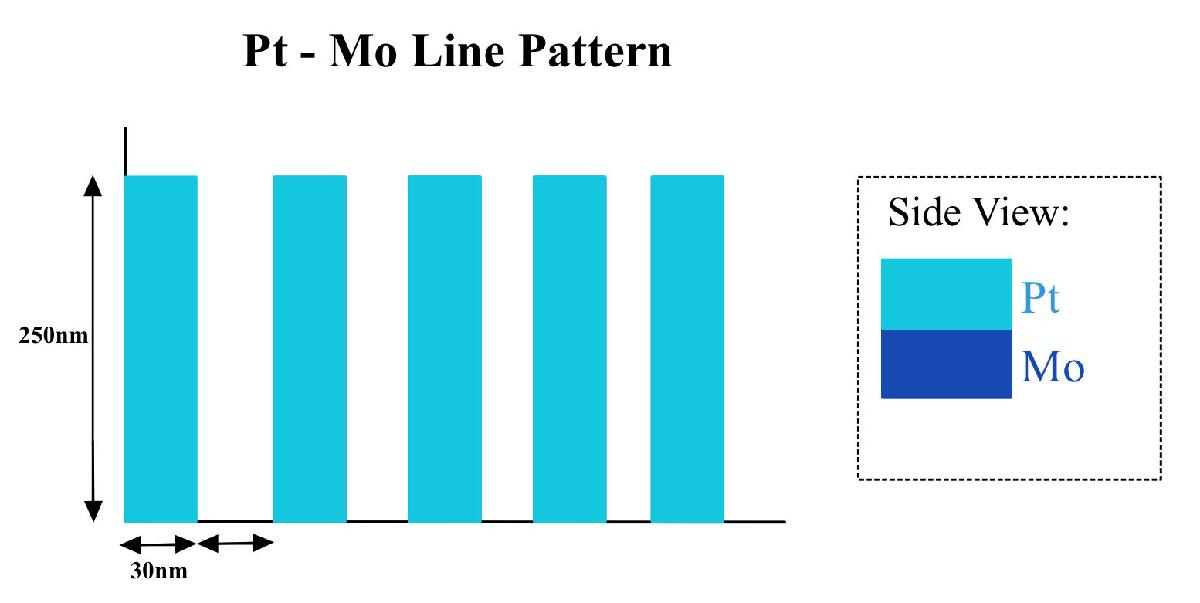

clear
mpm addpath

mpm: Adding cxro-intern-imaging-utils to MATLAB path
mpm: Adding ryan_toolbox to MATLAB path


tic
% photomask size
fineMesh = 1000;
x = linspace(0, 300, fineMesh);
y = linspace(0, 250, fineMesh);
[X, Y] = meshgrid(x, y);

% change thickness for specific point of interest
thickness = 2:2:40;

% remove this later:
% thickness = 40;

pixelsPerNanos = fineMesh/300;

trueRoughness = zeros(1, length(thickness));
chosenThreshold = zeros(1, length(thickness));
closestWidth = zeros(1, length(thickness));

% code for calculating the wave, in this specific example it is a tri-layer
% of PtMo in the rectangular pattern shown in the image above
for i = 1:length(thickness)
    
    fprintf('Computing thickness %0.1f, index %d/%d\n', thickness(i), i, length(thickness));
    
    % Bottom Mo region
    [wave1_Mo_Bot, idealMask1_Mo_Bot] = createRectangleTransmission(X, Y, [15, 125], 0, [30, 250, thickness(i)], 'Ru');
    [wave2_Mo_Bot, idealMask2_Mo_Bot] = createRectangleTransmission(X, Y, [75, 125], 0, [30, 250, thickness(i)], 'Ru');
    [wave3_Mo_Bot, idealMask3_Mo_Bot] = createRectangleTransmission(X, Y, [135, 125], 0, [30, 250, thickness(i)], 'Ru');
    [wave4_Mo_Bot, idealMask4_Mo_Bot] = createRectangleTransmission(X, Y, [195, 125], 0, [30, 250, thickness(i)], 'Ru');
    [wave5_Mo_Bot, idealMask5_Mo_Bot] = createRectangleTransmission(X, Y, [255, 125], 0, [30, 250, thickness(i)], 'Ru');
    
    wave_Mo_Bot = wave1_Mo_Bot.*wave2_Mo_Bot.*wave3_Mo_Bot.*wave4_Mo_Bot.*wave5_Mo_Bot;
    
    % Middle Pt Region
    [wave1_Pt, idealMask1_Pt] = createRectangleTransmission(X, Y, [15, 125], thickness(i), [30, 250, thickness(i)*2], 'TaN');
    [wave2_Pt, idealMask2_Pt] = createRectangleTransmission(X, Y, [75, 125], thickness(i), [30, 250, thickness(i)*2], 'TaN');
    [wave3_Pt, idealMask3_Pt] = createRectangleTransmission(X, Y, [135, 125], thickness(i), [30, 250, thickness(i)*2], 'TaN');
    [wave4_Pt, idealMask4_Pt] = createRectangleTransmission(X, Y, [195, 125], thickness(i), [30, 250, thickness(i)*2], 'TaN');
    [wave5_Pt, idealMask5_Pt] = createRectangleTransmission(X, Y, [255, 125], thickness(i), [30, 250, thickness(i)*2], 'TaN');
    
    wave_Pt = wave1_Pt.*wave2_Pt.*wave3_Pt.*wave4_Pt.*wave5_Pt;
    
    % Top Mo Region
    [wave1_Mo_Top, idealMask1_Mo_Top] = createRectangleTransmission(X, Y, [15, 125], thickness(i)*3, [30, 250, thickness(i)], 'Ru');
    [wave2_Mo_Top, idealMask2_Mo_Top] = createRectangleTransmission(X, Y, [75, 125], thickness(i)*3, [30, 250, thickness(i)], 'Ru');
    [wave3_Mo_Top, idealMask3_Mo_Top] = createRectangleTransmission(X, Y, [135, 125], thickness(i)*3, [30, 250, thickness(i)], 'Ru');
    [wave4_Mo_Top, idealMask4_Mo_Top] = createRectangleTransmission(X, Y, [195, 125], thickness(i)*3, [30, 250, thickness(i)], 'Ru');
    [wave5_Mo_Top, idealMask5_Mo_Top] = createRectangleTransmission(X, Y, [255, 125], thickness(i)*3, [30, 250, thickness(i)], 'Ru');
    
    wave_Mo_Top = wave1_Mo_Top.*wave2_Mo_Top.*wave3_Mo_Top.*wave4_Mo_Top.*wave5_Mo_Top;
    
    %Wave Total and Plotting
    wave_Tot = wave_Mo_Bot.*wave_Pt.*wave_Mo_Top;
    
    % Taking the absolute value of the imageSim ouput using the following parameters:
    % [250 250] plot size, 13.5 wavelength and 0.33 Numerical Aperture
    imageIntensity = abs(imageSim(wave_Tot, [300 250], 13.5, .35));
    
    % code that analyzes a specific region of the photomask... in this example,
    % we are taking a look at the rectangle pattern shown in the picture above
    % by taking in all the rows but only analyzing the first 50 columns
    % (rectangles exist in intervals of 100 i.e rectangle 1 = [0 100],
    % rectangle 3 = [400 500], rectangle 5 = [800 900]...
    % running a for loop to loop through 0 to 1 with a step of 0.01 to
    % find the 'optimal' threshold
    
    % Average N trials
    numTrials = 10;
    trialRough = [];
    trialThresh = [];
    trialWidth = [];
    
    for m = 1:numTrials
    [thresholded, latentImage, roughness, width, optimalThreshold, hasError] = imageToDeprotectionAutoThreshold(imageIntensity, [.3, .25], 50, 10, 80, 100);
        trialRough(m) = roughness;
        trialThresh(m) = optimalThreshold;
        trialWidth(m) = width;
    end
    
%     % Find optimal threshold
%     optimalThreshold = findOptimalThreshold(imageIntensity, [.3, .25], 100);
%     
%     % Find roughness at optimal threshold
%     findRough = imageToDeprotection(imageIntensity, [.3, .250], 50, 10, 40, optimalThreshold);
%     [width, roughness, hasError] = analyzeLines(findRough);
  
    
    errorFree = find(~hasError);
    trueRoughness(i) = mean(trialRough);
    chosenThreshold(i) = mean(trialThresh);
    closestWidth(i) = mean(trialWidth);
    
end

Computing thickness 2.0, index 1/20
Computing thickness 4.0, index 2/20
Computing thickness 6.0, index 3/20
Computing thickness 8.0, index 4/20
Computing thickness 10.0, index 5/20
Computing thickness 12.0, index 6/20
Computing thickness 14.0, index 7/20
Computing thickness 16.0, index 8/20
Computing thickness 18.0, index 9/20
Computing thickness 20.0, index 10/20
Computing thickness 22.0, index 11/20
Computing thickness 24.0, index 12/20
Computing thickness 26.0, index 13/20
Computing thickness 28.0, index 14/20
Computing thickness 30.0, index 15/20
Computing thickness 32.0, index 16/20
Computing thickness 34.0, index 17/20
Computing thickness 36.0, index 18/20
Computing thickness 38.0, index 19/20
Computing thickness 40.0, index 20/20


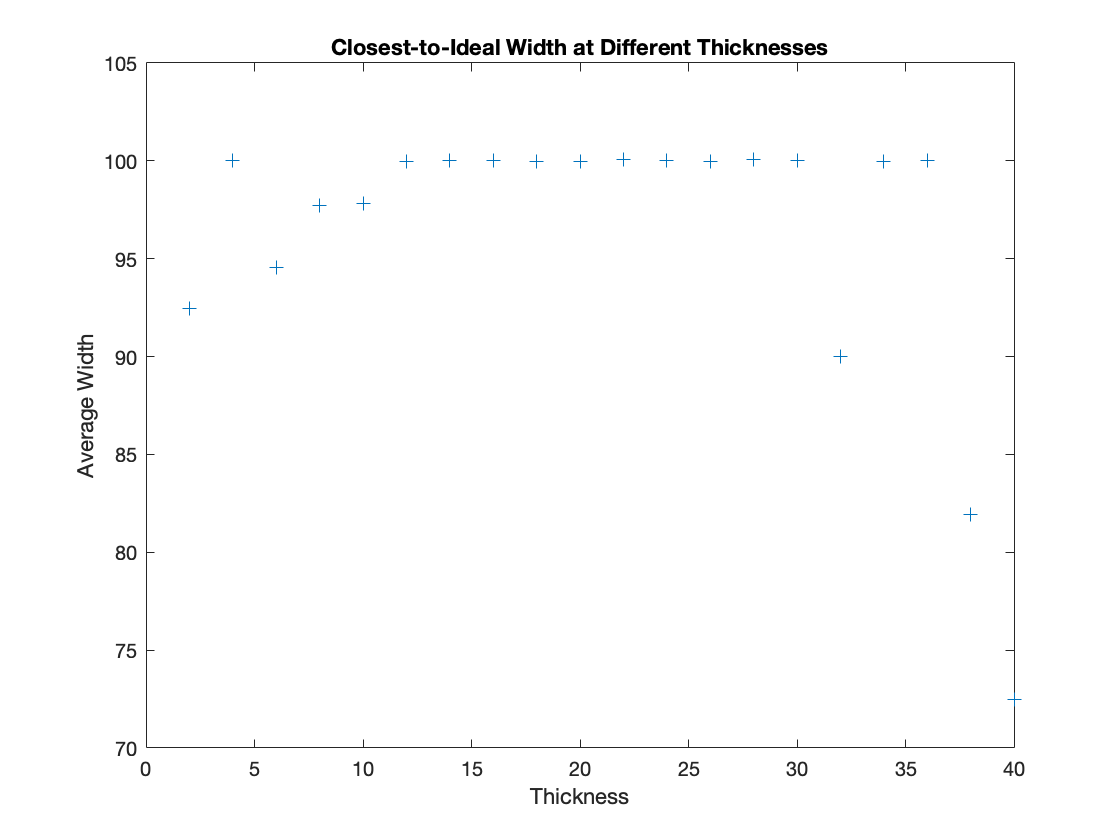

figure();

plot(thickness, closestWidth, '+')
xlabel('Thickness'); ylabel('Average Width');
% axis([10 60 90 110]);
title('Closest-to-Ideal Width at Different Thicknesses');

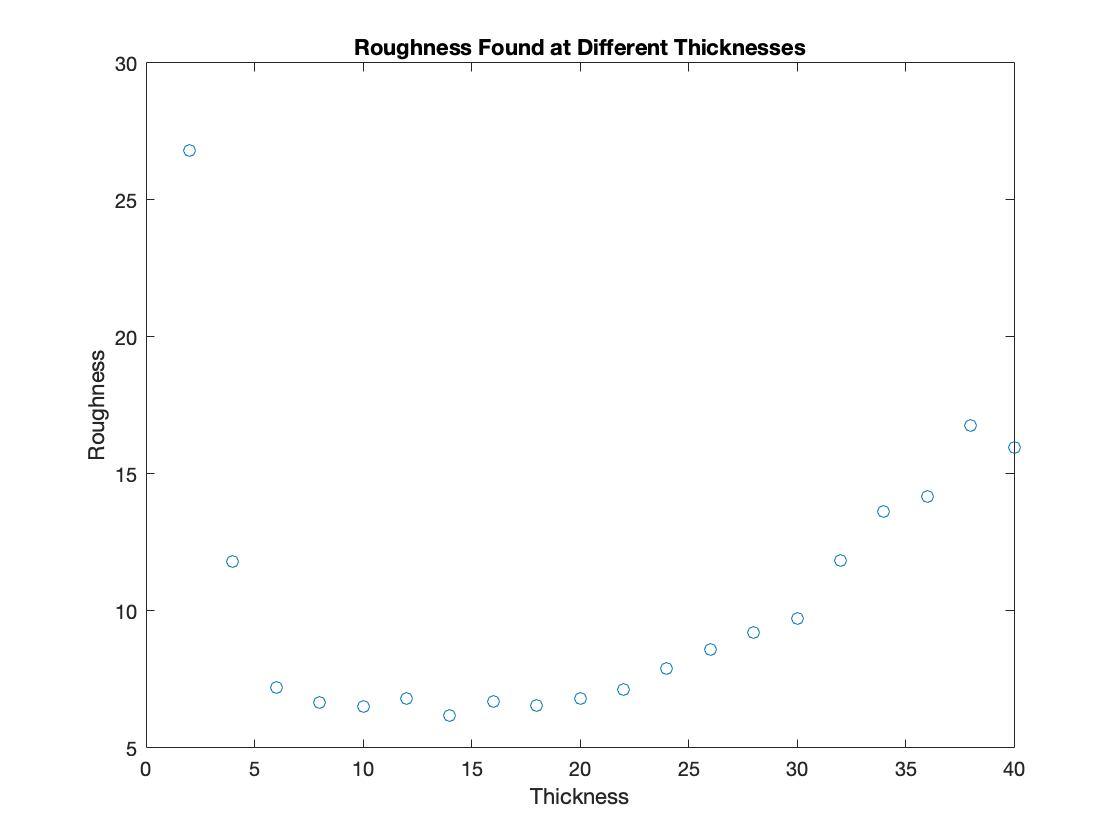

figure();

plot(thickness, trueRoughness, 'o')
xlabel('Thickness'); ylabel('Roughness');
% axis([10 60 1 10]);
title('Roughness Found at Different Thicknesses');

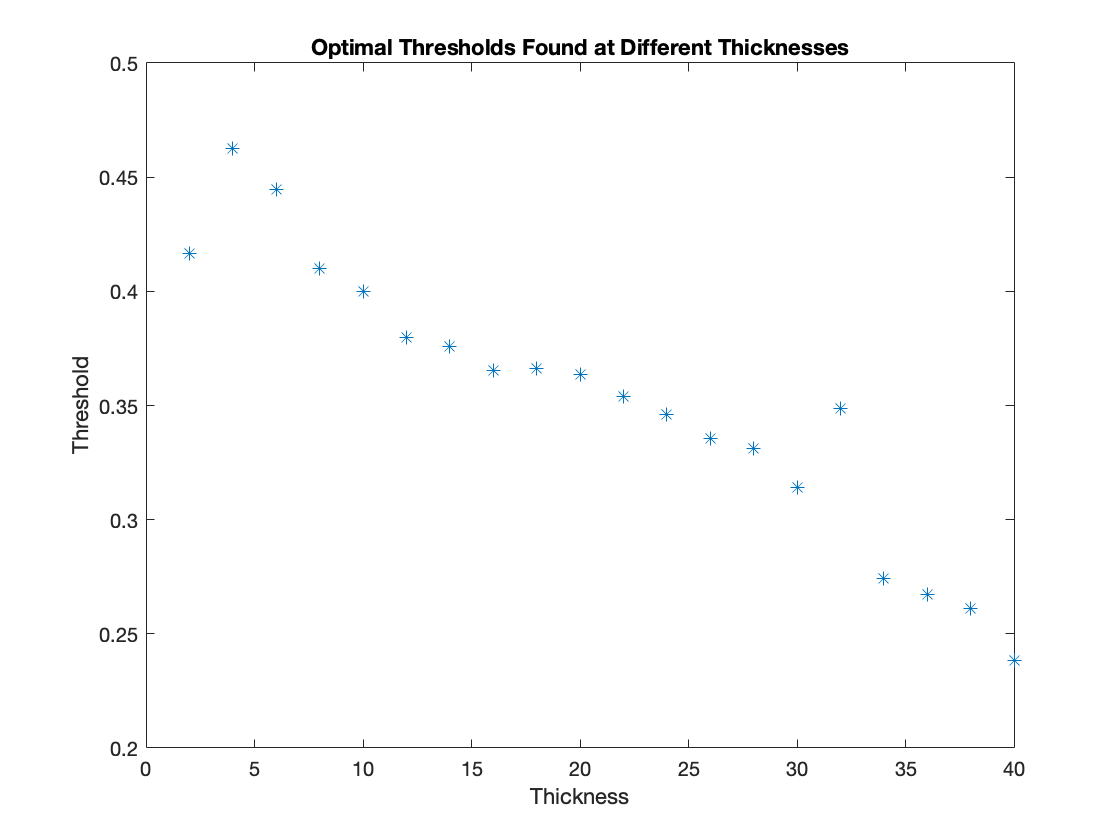

figure();

plot(thickness, chosenThreshold, '*')
xlabel('Thickness'); ylabel('Threshold');
% axis([10 60 0 1]);
title('Optimal Thresholds Found at Different Thicknesses');

fprintf('Simulation completed in %s\n', s2f(toc))

Simulation completed in 7m 19s.
